### Tokens:

### DVHG-HIFK

### KPUJ-AKU3

### 6XRX-8163

### QRBF-DWS2

### 1 Preparatory exercises 

**1. Let H1 and H2 be a pair of rectifying homographies and let F21 be the fundamental matrix between image 1 and image 2, before the homographies are applied. Which relation must H1 and H2 satisfy in order to be rectifying homographies? ANSWER: **


$$(H_1 ^{-1})^T F_{12}H_2^{-1} \tilde{} F_R = $$

$$\left\lbrack \begin{array}{ccc}
0 & 0 & 0\\
0 & 0 & -1\\
0 & 1 & 0
\end{array}\right\rbrack$$


**2. If the camera matrices are known, the fundamental matrix that relates corresponding points in image 1 and 2 can be computed from the cameras. How? Which information do you need and how do you compute it from the camera matrices? ANSWER: **

$F = [e_{12}]_XC_1C_2^+ \\
e_{12} = C_1n_2$ where n_2 are the homogeneous coordinates for the camera center for camera 2.

**3. In Section 3.1, the fundamental matrix is used to map points in one image to epipolar lines in the other image, inside a for-loop. Which computations take place inside the for-loop? Why? ANSWER: **

for ix=1:size(y1,2), 

    l1(:,ix)=-l1(:,ix)/norm(l1(1:2,ix))*sign(l1(3,ix)); 

    l2(:,ix)=-l2(:,ix)/norm(l2(1:2,ix))*sign(l2(3,ix)); 

end 

This is D-normalization for each line to be able to calculate distances.

**4. If you do an SVD of F: F = U S VT , what characteristic property do you expect to find for S in this case that F is a fundamental matrix? As a consequence, what information do you expect to find in the third column of U and V, respectively? ANSWER: **

The expectation is that we will get a zero-valued singular value in the diagonal of S and therefore we get the solution for the nullspace of F in the third column of V

**5. How can you compute the epipolar points from the matrix F21 representing the fundamental matrix? ANSWER: **

You take two points and calculate the epipolar lines with F21, then check where they intersect and then P-normalize.

Take the SVD and find them in the left and right null space of F21.

**6. Given the two epipoles, the Matlab function LoopZhangDistortion computes the error within a certain interval for λ and plots the error and its approximate derivative. Look at the code of this function (use Matlab command type) and verify that it performs the computations described in section 5.1 of the paper [2]. Does it? ANSWER: **

It looks right.

**7. In Section 3.2, the homographies Hp1, Hp2, Hr1 and Hr2 are computed in accordance with the rectification method of Loop and Zhang. Verify that the Matlab code works in accordance with [2]. In particular, verify that these calculations correspond to equations (16) and (17) in the paper2 . Do they? ANSWER**

It looks right. 

**8. In Section 3.3, the homographies H1 and H2 are used to rectify the two images, by applying them onto the pixel coordinates. Describe how the resulting homography T depends on H1 and H2. ANSWER: **

The homographies might morph the planes quite harshly so T is made to translate and scale everything back so that it fits within the same dimensions of the original images

**9. A possible solution to the problem of estimating rectifying homographies is to produce rectified images that are both upside down compared to what you expect. What transformation matrix on the homogeneous coordinates will flip vertical coordinates? ANSWER: **


$$\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & -1 & 0\\
0 & 0 & 1
\end{array}\right\rbrack$$


**10. In Section 4, the fundamental matrix is estimated from image data. The computations are found in the Matlab function fmatrix n8pa. Examine the file fmatrix n8pa and identify where in the function each step is implemented. Can you do that? ANSWER: **

row 22-37     % 1. Scale data with Hartley normalization

row 44-48     % 2. Estimate F

row 50-53     % 3. Enforce rank 2

row 55          % 4. Apply scaling to F

**11. What does it mean for the solution of the problem of estimating the fundamental matrix if there is more than one small singular value? ANSWER:**

We will get a higher dimension nullspace and therefore we don't have enough constraints to specify a finite set of solutions for the fundamental matrix

**12. In Section 5 you will need to compute the coordinates of a 3D point given its image coordinates in two images, y1 and y2, and the corresponding camera matrices C1 and C2. Write a Matlab function that computes the 3D coordinates xb from the image points and camera matrices, using one of the linear methods described in the lecture. ANSWER: slide 59,60**

    [U,S,V] = svd([liu_crossop(y1(:,ix))*C1; liu_crossop(y2(:,ix))*C2]);

    V_right = V(:,end);

    recpoint = V_right/V_right(4);

addpath(genpath('ExerciseD\'));

### 3 Rectifying homographies

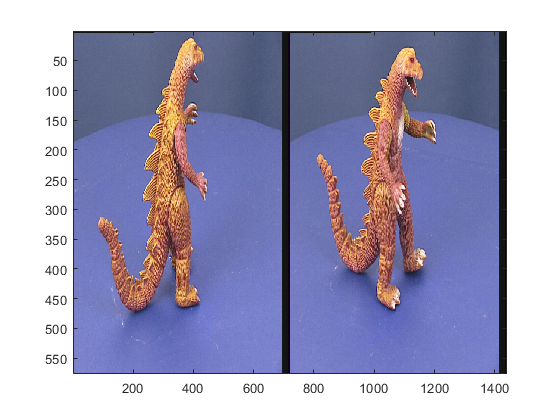

im1=imread('dinosaur0.png');
im2=imread('dinosaur5.png');
load('dino_Ps','P');
figure(1);clf;image([im1 im2]);

C1=P{1}; % The camera matrix corresponding to image 1
C2=P{6}; % The camera matrix corresponding to image 2

%calc camera centers and epipolar points
n1 = null(C1);
n2 = null(C2);
e12 = C1*n2;
e21 = C2*n1;

%calc fundamental matrix
F21 = liu_crossop(e21)*C2*pinv(C1);

%select correspondences
% [y1,y2]=correspondences_select(im1,im2);
% y1(end+1,:)=1; 
% y2(end+1,:)=1;

%saved correspondences
load('y1.mat');
load('y2.mat');

**QUESTION: With what accuracy can you determine the coordinates of corresponding points in these images? **

We are limited by the resolution or size of one pixel.

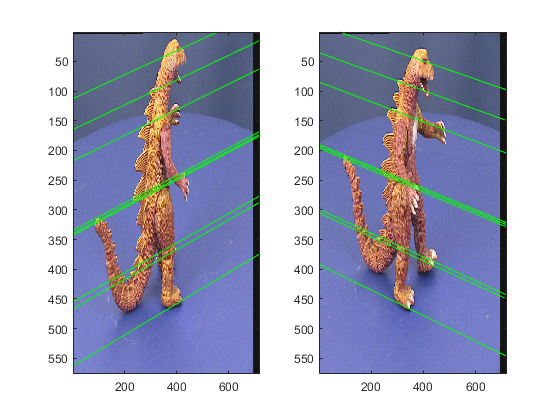

%epipolar lines
l2=F21*y1;
l1=F21'*y2;

%normalize
for ix=1:size(y1,2)
l1(:,ix)=-l1(:,ix)/norm(l1(1:2,ix))*sign(l1(3,ix));
l2(:,ix)=-l2(:,ix)/norm(l2(1:2,ix))*sign(l2(3,ix));
end

%draw the lines
figure(2);clf;
subplot(1,2,1);image(im1);hold on;
subplot(1,2,2);image(im2);hold on;
for k=1:size(y1,2)
subplot(1,2,1);plot(y1(1,k),y1(2,k));drawline(l1(:,k));
subplot(1,2,2);plot(y2(1,k),y2(2,k));drawline(l2(:,k));
end

**QUESTION: What are the Cartesian coordinates of the two epipoles? Where are they in the images? ANSWER: **

e12_normalized = e12/e12(3)

e12_normalized = 	1.0e+03 *

    7.3908
   -1.3773
    0.0010


e21_normalized = e21/e21(3)

e21_normalized = 	1.0e+03 *

   -6.4174
   -0.9879
    0.0010


In the images they are at infinity.

**QUESTION: Do the epipolar lines intersect with the corresponding points? Are the epipolar lines in each of the two images parallel? Is this result consistent with the positions of the epipoles?**

the lines intersect the corresponding points. The lines are parallell. Yes, since they intersect at the epipoles, which is at an ideal point.

%estimate errors
err1F21=abs(sum(y1.*l1))

err1F21 =     0.7504    1.0936    0.3933    1.1837    1.4427    0.6550    0.5854    3.1140    1.3793


err2F21=abs(sum(y2.*l2))

err2F21 =     0.7645    1.1256    0.3999    1.1679    1.3968    0.6125    0.5905    3.1102    1.4063


mean(err1F21)

ans = 1.1775

mean(err2F21)

ans = 1.1749

**QUESTION: Are the distances of the same order as the estimated accuracy? ANSWER:**

Yes, it is approximately 1.

**Use the Matlab code that you produced in preparatory exercise 5 to determine the two epipoles: **

%calc epipoles and P normalize
[u,s,v] = svd(F21);
e12a = v(:,3)/v(3,3)

e12a = 	1.0e+03 *

    7.3908
   -1.3773
    0.0010


e21a = u(:,3)/u(3,3)

e21a = 	1.0e+03 *

   -6.4174
   -0.9879
    0.0010


**QUESTION: Did you get epipolar points that are consistent with your observed epipolar lines?**

Yes

### 3.2 The Loop & Zhang method

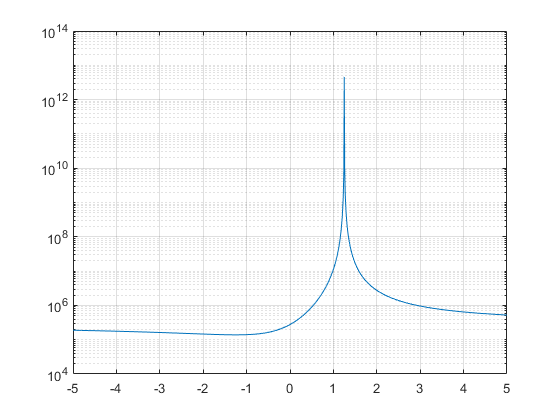

w=720;h=576; % Image width and height
lambda = -5:0.01:5; %Replace with the interval you choose
dist = LoopZhangDistortion(e12,e21,w,h,lambda);
figure
plot(lambda,dist);
set(gca,'YScale','log');grid on;

lmin = lambda(dist==min(dist)) %Print minimum lambda

lmin = -1.2500


%verify with derivative
Df = diff(dist);
[~, index] = min(abs(Df));
lm = -5+(index-1)*0.01

lm = -1.2500

**QUESTION: How did you verify that you have found the minimum?**

Checked the differential to find local minima

**QUESTION: What value of λ gives the minimal error?**

-1.25

%Compute the projective homographies for the two images given by this λ
lambda = lmin; % Insert your value here
w1=liu_crossop(e12)*[lambda 1 0]';
w1=w1/w1(3);
w2=F21*[lambda 1 0]';
w2=w2/w2(3);
Hp1=[1 0 0;0 1 0;w1'];
Hp2=[1 0 0;0 1 0;w2'];

%calc homographies
vcp=0;
Hr1=[F21(3,2)-w1(2)*F21(3,3) w1(1)*F21(3,3)-F21(3,1) 0;
F21(3,1)-w1(1)*F21(3,3) F21(3,2)-w1(2)*F21(3,3) F21(3,3)+vcp;
0 0 1]

Hr1 = 	1.0e+03 *

   -0.0197    0.0037         0
   -0.0037   -0.0197    2.5172
         0         0    0.0010


Hr2=[w2(2)*F21(3,3)-F21(2,3) F21(1,3)-w2(1)*F21(3,3) 0;
w2(1)*F21(3,3)-F21(1,3) w2(2)*F21(3,3)-F21(2,3) vcp;
0 0 1]

Hr2 =   -23.1745   -3.5673         0
    3.5673  -23.1745         0
         0         0    1.0000


**QUESTION: Given the homographies that you now have computed, how can you verify this relation? Does it work?**

If they fulfill criteria in prep exercise 1 then they work.

flip = [-1,0,0;0,-1,0;0,0,1]; %flip added for later exercise
H1 = flip*Hr1*Hp1; 
H2 = flip*Hr2*Hp2;
Fr = inv(H2)'*F21*inv(H1) %should be Fr up to scale

Fr =    -0.0000    0.0000    0.0000
    0.0000    0.0000    1.0000
    0.0000   -1.0000    0.0000


Which is correct so yes it does work.

%scaling and translating for rectifying
oldcorners=[1 w w 1;1 1 h h];
newcorners1=map_points(H1,oldcorners);
newcorners2=map_points(H2,oldcorners);
mincol=min([newcorners1(1,:) newcorners2(1,:)]);
minrow=min([newcorners1(2,:) newcorners2(2,:)]);
T=[1 0 -mincol+1;0 1 -minrow+1;0 0 1]

T = 	1.0e+03 *

    0.0010         0    2.3969
         0    0.0010    2.4948
         0         0    0.0010


newcorners1=map_points(T*H1,oldcorners);
newcorners2=map_points(T*H2,oldcorners);
maxcol=max([newcorners1(1,:) newcorners2(1,:)]);
maxrow=max([newcorners1(2,:) newcorners2(2,:)]);
T=inv(diag([maxcol/w maxrow/h 1]))*T

T =     0.0338         0   81.0435
         0    0.0308   76.8540
         0         0    1.0000


**QUESTION: How can you see that T is a scaling and translation transformation?**

Since it is a similarity transform without rotation or reflection we only have scaling and translation.

%transform and display result
imr1=image_resample(double(im1),T*H1,h,w);
imr2=image_resample(double(im2),T*H2,h,w);
figure(3);image(uint8([imr1 imr2]));hold on;
y2t = map_points(T*H2,y2(1:2,:))

y2t =   386.2322  457.5108  409.4869  318.2655  300.0393  205.4623  428.8456  384.7828  478.7729
   69.2796  137.7992  222.0167  102.9952  218.2351  224.0390  388.8462  305.7346  314.5541


y1t = map_points(T*H1,y1(1:2,:))

y1t =   373.3016  368.1844  377.2725  280.9522  216.5445  122.8155  352.0892  321.4483  339.9113
   68.7634  138.5913  221.7131  102.1735  219.3156  224.5234  388.3395  308.2668  313.4234


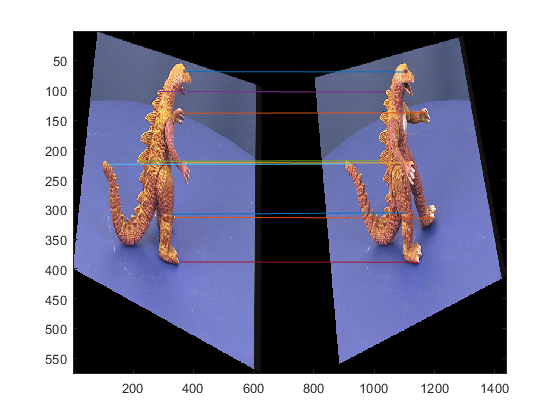


for k=1:size(y1t,2)
     plot([y1t(1,k) y2t(1,k)+size(im1,2)], [y1t(2,k) y2t(2,k)])
end
hold off

**QUESTION: Do the transformed images and points appear rectified?**

Yes

### 4 The fundamental matrix and the 8-point algorithm

%non-normalized 8 point alg 
F = fmatrix_nn8pa(y1,y2)

Singular values of data matrix:


ans = 	1.0e+05 *

    6.4143    2.0614    0.3918    0.2945    0.0024    0.0010    0.0003    0.0001    0.0000


F =    -0.0000   -0.0000   -0.0007
   -0.0000   -0.0000    0.0121
   -0.0018   -0.0099    0.9999


ans = 1.1749

y1

y1 =   410.3387  412.2742  432.5968  297.1129  235.1774  116.1452  420.9839  376.4677  398.7258
   29.1452  129.7903  239.1452  101.7258  281.7258  316.5645  452.0484  364.9516  365.9194
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


y2

y2 =   407.4355  480.0161  381.3065  300.9839  240.0161  120.0161  348.4032  320.3387  438.4032
   51.4032  163.6613  263.3387   84.3065  232.3710  217.8548  467.5323  360.1129  394.9516
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


The function prints the singular values of the data matrix A and, ideally, there should be a only one of them that is significantly smaller than the others.

**QUESTION: Is this the case?**

`Yes`

**Compare this new estimate of the fundamental matrix to the matrix F21 determined in the previous section. QUESTION: How can you do this comparison?**

We could for example normalize both F21 and F by dividing with the last element and compare the elements.

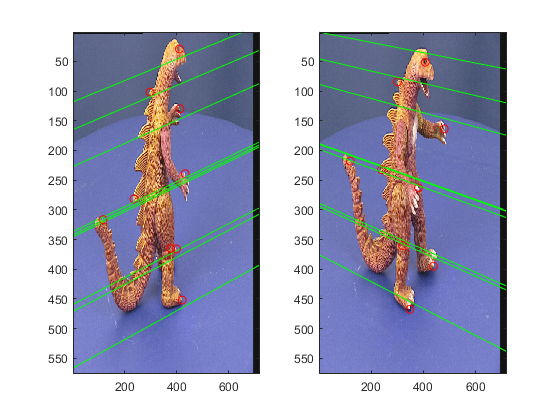

%compare F with F21
figure;clf;
subplot(1,2,1);image(im1);hold on;
subplot(1,2,2);image(im2);hold on;
l2=F*y1;
l1=F'*y2;
for k=1:size(y1,2),
l1(:,k)=-l1(:,k)/norm(l1(1:2,k))*sign(l1(3,k)); %Normalise dual
l2(:,k)=-l2(:,k)/norm(l2(1:2,k))*sign(l2(3,k)); %homog. coord.
end
for k=1:size(y1,2),
subplot(1,2,1);plot(y1(1,k),y1(2,k),'or');drawline(l1(:,k));
subplot(1,2,2);plot(y2(1,k),y2(2,k),'or');drawline(l2(:,k));    
end

err1F=abs(sum(y1.*l1));
err2F=abs(sum(y2.*l2));

%means of errors
mean(err1F)

ans = 10.6729

mean(err2F)

ans = 10.8160

mean(err1F21)

ans = 1.1775

mean(err2F21)

ans = 1.1749

**QUESTION: Is F a better or worse estimate of the fundamental matrix compared to F21? Why?**

F21 is calculated directly from the camera matrices while F is first calculated from point correspondences that are not very carefully chosen.

### 5 Triangulation

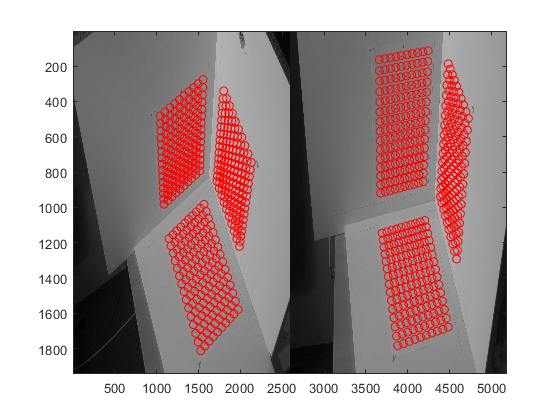

%load data
load('tridata','x','y1','y2','im1','im2','C1','C2');
figure(1);image([im1 im2]);
colormap(gray(256));hold on;
for k=1:size(y1,2),
plot(y1(2,k),y1(1,k),'ro');
plot(y2(2,k)+size(im1,2),y2(1,k),'ro');
end
hold off;

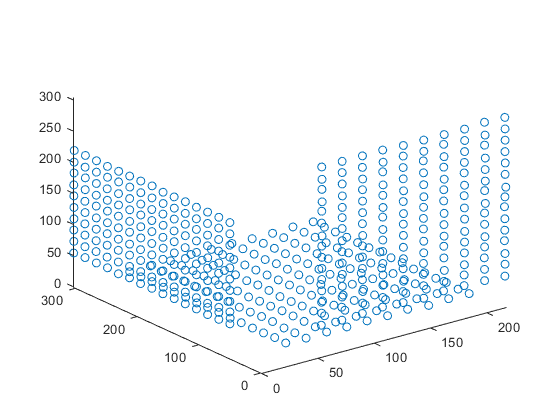


%reconstruct points
xrec=[];
for ix=1:length(y1),
    
    %use svd 
    [U,S,V] = svd([liu_crossop(y1(:,ix))*C1; liu_crossop(y2(:,ix))*C2]);
    V_right = V(:,end);
    recpoint = V_right/V_right(4);
    
    xrec=[xrec recpoint];
end

figure(3);plot3(xrec(1,:),xrec(2,:),xrec(3,:),'o');

**Plot the 3D coordinates and verify that the reconstructed points appear as they should: QUESTION: Do they?**

Yes

**QUESTION: Compute the error in the reconstructed 3D coordinates relative to the true 3D coordinates in x (units in mm). What is the mean of the error, and what is its standard deviation?**

%make error array
error = [];
for i = 1:size(x,2)
    tmp = sqrt(sum((x(:, i)-xrec(:, i)).^2));
    error = [error, tmp];
end

mean_error = mean(error) %in mm

mean_error = 0.5920

stdev_error = std(error) 

stdev_error = 0.4547

**QUESTION: Compute the reprojection error by projecting the estimated 3D points into each of the two images and computing the error relative to the given image coordinates in y1 and y2 (units in pixels). What is the mean and standard deviation?**

%reconstructing y1 and y2
y1_rec = C1*xrec;
y2_rec = C2*xrec;
for i = 1:size(y1_rec,2)
    y1_rec(:,i) = y1_rec(:,i)/y1_rec(3,i);
    y2_rec(:,i) = y2_rec(:,i)/y2_rec(3,i);
end

%error for y1_rec
y1_error = [];
for i = 1:size(y1,2)
    tmp = sqrt(sum((y1(:, i)-y1_rec(:, i)).^2));
    y1_error = [y1_error, tmp];
end
mean_y1_error = mean(y1_error)

mean_y1_error = 0.3196

stdev_y1_error = std(y1_error)

stdev_y1_error = 0.2330


%error for y2_rec
y2_error = [];
for i = 1:size(y2,2)
    tmp = sqrt(sum((y2(:, i)-y2_rec(:, i)).^2));
    y2_error = [y2_error, tmp];
end
mean_y2_error = mean(y2_error)

mean_y2_error = 0.4141

stdev_y2_error = std(y2_error)

stdev_y2_error = 0.3516